# 3주차 — 블록선도, 상태공간, 선형화

**제어시스템설계** · 충남대학교 자율운항시스템공학과

**참고자료 — 먼저 볼 것**

아래 다섯 과목은 **이 강의의 담당교수가 직접 한 강의**입니다. 기초부터 대학원 과정까지 이어지므로 부족한 곳부터 보면 됩니다. 이 강의에서 쓰는 기호와 유도는 모두 그 안에서 자세히 다룹니다.

**MATLAB 이나 Simulink 가 아직 익숙하지 않다면** 실습에 들어가기 전에 아래를 먼저 하십시오. 무료이고 각각 몇 시간이면 끝납니다.

오늘은 세 가지를 합니다. 앞의 둘은 도구이고 **마지막 하나가 진짜 중요합니다.**

- 블록선도 합치기 — 여러 개를 하나로

- 상태공간 — 시스템을 적는 두 번째 방법

- **선형화** — 굽은 것을 곧게 펴서 쓰기

셋 중 하나만 가져간다면 세 번째를 가져가십시오.

**오늘의 한 줄**

세상은 굽어 있는데(비선형) 우리 도구는 곧은 것(선형)만 다룹니다. 그래서 관심 있는 지점 근처만 곧게 펴서 씁니다. 이게 선형화입니다.

if isempty(which('plant_msd'))   % 경로가 아직 등록 안 되었으면 알아서 잡는다
    p_ = pwd;
    if ~isempty(mfilename('fullpath')), p_ = fileparts(mfilename('fullpath')); end
    for k_ = 1:4
        if isfile(fullfile(p_,'setup_path.m')), run(fullfile(p_,'setup_path.m')); break; end
        p_ = fileparts(p_);
    end
    clear p_ k_
end
clc; close all;
s = tf('s');

## 0-0. 오늘 돌려 볼 파일

강의노트를 읽다가 **직접 값을 바꿔 보고 싶을 때** 여는 파일들입니다. 모두 `W03_StateSpace_Linearization` 폴더 안에 있고, 강의노트의 절 번호와 스크립트의 절 번호가 서로 맞도록 만들어 두었습니다.

실행하는 법 — 파일을 열고 절 안에서 `Ctrl+Enter` 를 누르면 그 절만 돕니다. 전체를 돌리려면 `F5` 입니다. 처음 한 번은 `setup_path` 를 먼저 실행하십시오.

이 강의노트에 실린 **그림은 전부** `make_figures.m` 이 만들어 `common/figures/` 에 넣어 둔 것입니다. 그림마다 어느 함수가 만들었는지 아래에 적어 두었으니, 바꿔 보고 싶으면 그 함수를 열면 됩니다.

## 0. 오늘 한 장 요약

오늘은 세 가지를 합니다. 서로 이어져 있습니다.

- **블록선도 축약** — 여러 상자를 하나로 합치는 법 (규칙 세 줄)

- **상태공간** — 시스템을 다른 방식으로 적는 법

- **선형화** — 곡선을 직선으로 바꿔 우리 도구를 쓸 수 있게 하는 법

오늘의 계단

- **1~3절** 블록선도 세 규칙, 그리고 센서가 이상하면 생기는 일

- **4~6절** 상태란 무엇인가 (게임 세이브 파일)

- **7~9절** 오늘의 본론. 선형화의 근거인 테일러 급수와 야코비안, 그리고 동작점(평형점)과 편차 변수

- **10~12절** 진자에 적용. $\sin\theta \approx \theta$ 가 언제까지 통하는가

- **13절** Simulink 로 비선형과 선형을 나란히 놓고, `linearize` 로 자동 선형화한 뒤 네 방법의 답을 대조하고 **유효 범위를 숫자로 정하기**

- **14절** 왜 이 과목은 처음부터 끝까지 선형 모델을 기준으로 두는가

오늘 딱 하나만 기억한다면 이것입니다.

- **선형 제어기는 동작점 근처에서만 맞다**

## 0-1. 가장 작은 예부터 — 상자 두 개 합치기

이해를 돕기 위해 제일 쉬운 것부터 봅니다. 상자 두 개가 이어져 있으면 곱합니다.


$$G_1(s) = \frac{1}{s+1}, \qquad G_2(s) = \frac{2}{s+2} \qquad \Rightarrow \qquad G_1 G_2 = \frac{2}{(s+1)(s+2)}$$


dg_new(10, 2.6, '직렬 : 이어 붙이면 곱한다');
b1 = dg_block(3.5, 1.3, 1.8, 1.0, 'G_1(s)', [0.88 0.93 1.00]);
b2 = dg_block(6.5, 1.3, 1.8, 1.0, 'G_2(s)', [0.93 0.93 0.93]);
dg_arrow([1.0 1.3], b1.L, 'u');
dg_arrow(b1.R, b2.L, '');
dg_arrow(b2.R, [9.2 1.3], 'y');

G1 = 1/(s+1);
G2 = 2/(s+2);
fprintf('직렬로 이으면\n');
minreal(G1*G2)
fprintf('  극점 : %s   (두 시스템의 극점이 그대로 모입니다)\n\n', ...
        mat2str(round(pole(G1*G2).', 3)));

## 1. 블록선도 — 외울 것은 세 줄뿐

실제 시스템은 제어기, 모터, 기계, 센서가 줄줄이 이어져 있습니다. 이걸 하나로 합치는 규칙은 딱 세 개입니다.

- **직렬** — 곱한다. $G_1 G_2$

- **병렬** — 더한다. $G_1 + G_2$

- **되먹임** — $\frac{G}{1+GH}$

직렬이 곱셈인 이유는 환율 계산과 같습니다. 원 → 달러, 달러 → 유로로 갈 때 두 배율을 곱하는 것과 똑같습니다.

세 규칙을 한 장에 모으면 이렇게 됩니다. **이 그림 한 장이 오늘 1~3절 전부입니다.**

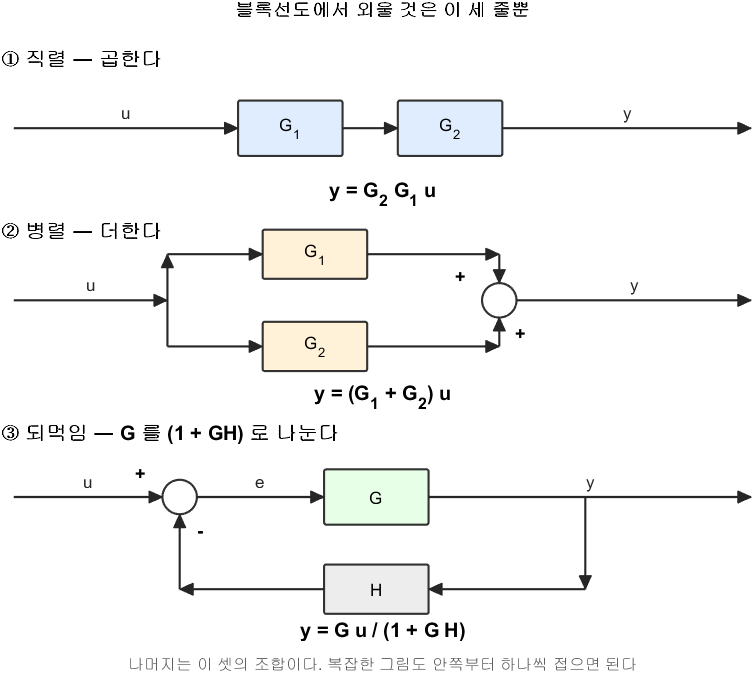

블록선도에서 외울 것은 이 세 줄뿐

**그림 파일** `block_rules.png` — `common/dg_block_rules.m` 의 `dg_block_rules` · 다시 만들려면 `make_figures('block_rules')`

**만드는 곳** — `common/dg_block_rules.m` (`make_figures('block_rules')` 로 다시 그립니다) **직접 확인해 보려면** — `W03_01_block_reduction.m` 의 **2·3·4절**을 차례로 실행하면 이 세 줄이 실제 숫자로 맞는지 하나씩 대조해 줍니다

그림 해석

셋 중 ③ 하나만 확실히 하십시오. ①과 ②는 상식이고, 이 과목이 학기 내내 들여다보는 것은 ③의 **분모**입니다.

## 2. 되먹임 공식은 세 줄이면 유도됩니다

외우는 것보다 유도해 보는 게 빠릅니다.


$$e = r - y, \qquad y = Ge$$


둘째 식에 첫째 식을 넣으면


$$y = G(r-y) \;\Longrightarrow\; y(1+G) = Gr \;\Longrightarrow\; \frac{y}{r} = \frac{G}{1+G}$$


기억할 형태는 이것입니다.


$$\text{폐루프} = \frac{\text{앞으로 가는 길}}{1 + \text{한 바퀴 도는 길}}$$


분모의 "$1+$ 한 바퀴"가 앞으로 이 과목 내내 나옵니다. 6주차 근궤적도, 10주차 안정여유도 결국 이 식을 들여다보는 일입니다.

## 3. 센서가 이상하면 출력도 이상해집니다

현실에서는 출력을 그대로 되돌리지 않고 센서로 재서 되돌립니다. 그래서 분모의 "한 바퀴"가 $GH$ 가 됩니다.

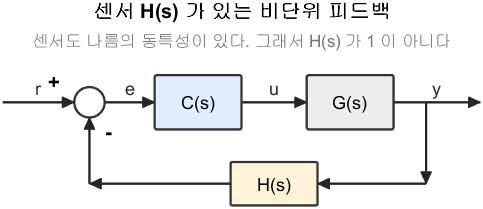

센서 H(s) 가 있는 비단위 피드백 — 되돌아오는 값이 y 가 아니라 H y 다

**그림 파일** `loop_sensor.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_sensor')`

**만드는 곳** — `common/dg_loop.m` 을 `dg_loop('sensor', ...)` 로 부릅니다 (`make_figures('loop_sensor')`) **직접 확인해 보려면** — `W03_01_block_reduction.m` 의 **5절**

그림 해석

여기서 꼭 알아 둘 것이 있습니다.

체온계가 고장 나서 실제보다 3배로 표시된다고 합니다. 환자 체온이 12도인데 체온계는 36도라고 보여 줍니다. 의사는 "정상이네" 하고 넘어갑니다.

**제어기도 똑같습니다.** 제어기는 센서가 보여 주는 값만 믿습니다. 센서 값이 목표와 같아지면 거기서 멈춥니다. 실제 출력은 어긋난 채로요.

아래에서 센서 이득이 3배인 경우를 확인해 봅니다.

G = 1/(s+1) * 20/(s+2);
H = 3/(0.2*s+1);
t = 0:0.01:10;
plot(t, step(feedback(G,1), t), 'LineWidth',2); hold on
plot(t, step(feedback(G,H), t), 'LineWidth',2)
yline(1,'k--','LineWidth',1.5); grid on
xlabel('시간 [s]'); ylabel('출력')
title('센서가 3배로 부풀려 읽으면 출력은 1/3 에서 멈춘다')
legend('센서 정상','센서 3배 오류','목표값','Location','southeast')

## 4. 상태공간 — "상태" 란 무엇인가

게임 세이브 파일을 생각해 봅니다.

게임을 저장하고 껐다가 내일 이어서 하려면 무엇을 저장해야 하는가? 캐릭터 위치, 체력, 아이템 정도면 됩니다. **지금까지 어떤 경로로 걸어왔는지는 저장할 필요가 없습니다.** 현재 상황만 알면 이어서 할 수 있기 때문입니다.

제어공학에서 **상태**(state)가 바로 이것입니다.


$$\text{상태} = \text{지금부터의 미래를 계산하는 데 필요한 최소한의 정보}$$


질량-스프링-댐퍼에서는 무엇이 필요한가?

- **위치만?** 부족합니다. 같은 위치라도 날아가는 중인지 멈춰 있는지 다릅니다

- **위치 **$+$** 속도?** 충분합니다. 이 둘과 앞으로 들어올 힘만 알면 미래가 다 정해집니다

그래서 이 시스템의 상태는 두 개입니다. 상태 개수는 미분방정식의 차수와 같습니다. 2계 미분방정식이면 상태 2개입니다.

**말로만 하면 안 믿기니 직접 봅니다.** 아래 세 경우는 **출발 위치가 모두 **$1\,\mathrm{m}$** 로 똑같습니다.** 다른 것은 놓는 순간의 속도뿐입니다.

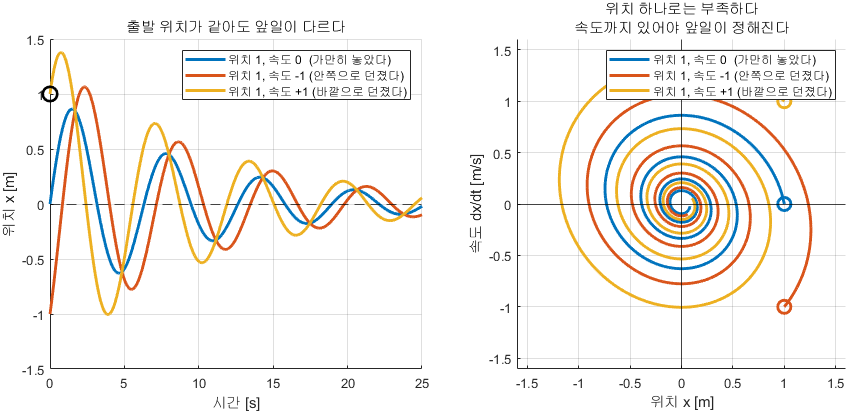

위치가 같아도 속도가 다르면 앞일이 완전히 다르다

**그림 파일** `w03_state_meaning.png` — `make_figures.m` 의 `fig_w03_state_meaning` · 다시 만들려면 `make_figures('w03_state_meaning')`

**만드는 곳** — `make_figures.m` 의 `fig_w03_state_meaning` **직접 바꿔 보려면** — `W03_02_state_space.m` 의 **6절**에서 초기조건 `x0 = [1; 0]` 의 두 번째 숫자를 바꿔 실행

그림 해석

**오른쪽 그림에서 세 곡선이 서로 만나지 않는다**는 것이 오늘 4절의 전부입니다. 위치 하나만 보면 세 경우가 같은 점이지만, $(x,\dot{x})$ 쌍으로 보면 다른 점입니다. 이 쌍이 곧 **상태**이고, 상태를 알면 앞일이 하나로 정해집니다.

## 5. 상태공간은 항상 두 줄입니다

형태가 언제나 똑같습니다. 이것만 기억하면 됩니다.


$$\dot{x} = Ax + Bu$$



$$y = Cx + Du$$


네 행렬의 역할을 이름이 아니라 **뜻으로** 기억하십시오.

- $A$ — 아무도 안 건드려도 시스템이 저 혼자 어떻게 움직이는가

- $B$ — 입력이 어느 상태를 얼마나 밀어 주는가

- $C$ — 여러 상태 중 우리가 실제로 볼 수 있는 것은 무엇인가

- $D$ — 입력이 출력에 곧바로 튀어나오는 몫 (대개 $0$)

두 줄을 블록선도로 그리면 왜 이 네 글자뿐인지 한눈에 보입니다.

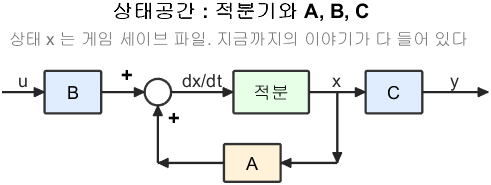

상태공간 두 줄을 블록선도로 그리면 이렇게 된다

**그림 파일** `loop_statespace.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_statespace')`

**만드는 곳** — `common/dg_loop.m` 을 `dg_loop('statespace', ...)` 로 부릅니다 (`make_figures('loop_statespace')`) **직접 확인해 보려면** — `W03_02_state_space.m` 의 **3절**이 네 행렬의 뜻을 숫자로 하나씩 보여 줍니다

그림 해석

$D$ 는 이 그림에 없습니다. $u$ 에서 $y$ 로 **적분기를 안 거치고 바로 가는 선**이 $D$ 인데, 대개 $0$ 이라 아예 그리지 않습니다.

이 중 $A$ 가 가장 중요합니다. 시스템의 성격을 $A$ 가 혼자 다 정합니다. 실제로 $A$** 의 고유값이 곧 전달함수의 극점**입니다. 확인해 봅니다.

[G_msd, p] = plant_msd();
disp('A 의 고유값:');    disp(eig(p.A))
disp('전달함수의 극점:'); disp(pole(G_msd))

## 5-1. 미분방정식을 상태공간으로 — 손으로 해 봅니다

2주차에서 세운 식을 그대로 가져옵니다.


$$m\,\ddot{x} + b\,\dot{x} + k\,x = F$$


절차는 **네 단계**입니다. 매번 똑같습니다.

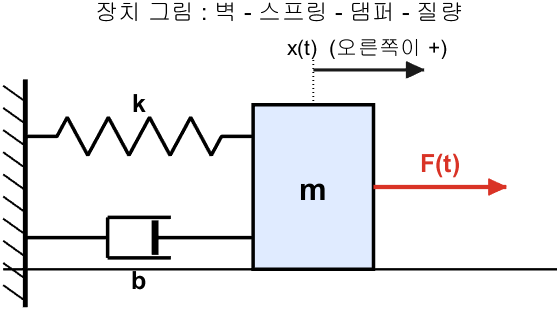

2주차에서 쓰던 그 장치 그대로다

**그림 파일** `msd_only.png` — `common/dg_msd.m` 의 `dg_msd` · 다시 만들려면 `make_figures('msd_only')`

**만드는 곳** — `common/dg_msd.m` 을 `dg_msd('system')` 으로 부릅니다 (`make_figures('msd_only')`) **직접 확인해 보려면** — `W03_02_state_space.m` 의 **2절**이 아래 네 단계를 그대로 코드로 밟습니다

그림 해석

## 5-2. 1단계 — 상태를 고른다

규칙 하나면 됩니다.

- **가장 높은 미분보다 한 단계 낮은 것까지** 를 상태로 잡는다

여기서는 가장 높은 미분이 $\ddot{x}$ (2계)이므로 $x$ 와 $\dot{x}$ 를 잡습니다.


$$x_1 = x \quad (\text{위치}), \qquad x_2 = \dot{x} \quad (\text{속도})$$


왜 이렇게 잡는가 — **이 둘만 알면 앞으로 벌어질 일이 전부 정해지기** 때문입니다. 지금 어디에 있고 얼마나 빨리 가고 있는지를 알면, 그다음은 물리 법칙이 정해 줍니다. 게임 세이브 파일에 저장해야 할 것이 딱 이 둘입니다.

**상태를 고르는 더 좋은 기준 — 에너지**

혼동될 때는 "**에너지를 저장하는 곳이 어디인가**" 를 물어보십시오. 저장된 에너지 하나가 상태 하나입니다.

댐퍼는 에너지를 **버리기만** 하고 저장하지 않습니다. 그래서 상태가 아닙니다. 이 기준은 어느 시스템에나 통합니다.

- RC 회로 — 커패시터가 에너지를 저장하니 상태 하나 (1차)

- RLC 회로 — 커패시터와 인덕터, 상태 둘 (2차)

- DC 모터 — 인덕터(전류)와 관성(각속도), 상태 둘

## 5-3. 2단계 — 각 상태의 미분을 상태와 입력으로만 적는다

**오른쪽에 **$x_1$**, **$x_2$**, **$u$** 말고 다른 것이 남으면 안 됩니다.**

첫 줄은 정의에서 바로 나옵니다.


$$\dot{x}_1 = \dot{x} = x_2$$


둘째 줄은 운동방정식을 $\ddot{x}$ 에 대해 풀면 됩니다.


$$m\,\ddot{x} = F - b\,\dot{x} - k\,x$$



$$\ddot{x} = \frac{1}{m}\left(F - b\,\dot{x} - k\,x\right)$$


여기에 $x = x_1$, $\dot{x} = x_2$, $F = u$ 를 넣으면


$$\dot{x}_2 = -\frac{k}{m}\,x_1 - \frac{b}{m}\,x_2 + \frac{1}{m}\,u$$


오른쪽에 $x_1$, $x_2$, $u$ 만 남았습니다. 성공입니다.

## 5-4. 3단계 — 행렬로 묶는다

두 줄을 그대로 세로로 세우고 계수만 뽑아 씁니다.


$$\begin{array}{l} \dot{x}_1 = 0\cdot x_1 + 1\cdot x_2 + 0\cdot u \\ \dot{x}_2 = -\frac{k}{m}\,x_1 - \frac{b}{m}\,x_2 + \frac{1}{m}\,u \end{array}$$


계수를 그대로 옮겨 적으면 $A$ 와 $B$ 가 나옵니다.


$$\left[\begin{array}{c}\dot{x}_1\\ \dot{x}_2\end{array}\right] = \left[\begin{array}{cc} 0 & 1\\ -\frac{k}{m} & -\frac{b}{m}\end{array}\right] \left[\begin{array}{c}x_1\\ x_2\end{array}\right] + \left[\begin{array}{c}0\\ \frac{1}{m}\end{array}\right] u$$


**첫 줄이 항상 **$[0\;\;1]$** 인 것**을 눈여겨보십시오. "위치의 미분은 속도" 라는 정의에서 나온 것이라 어느 2차 시스템이든 똑같습니다.

## 5-5. 4단계 — 출력을 고른다

우리가 재는 것이 위치라면


$$y = x = x_1 = \left[\begin{array}{cc}1 & 0\end{array}\right] \left[\begin{array}{c}x_1\\ x_2\end{array}\right] + 0\cdot u$$


이므로 $C = [1\;\;0]$, $D = 0$ 입니다.

속도를 잰다면 $C = [0\;\;1]$ 이 되고, 둘 다 잰다면 $C$ 가 $2\times 2$ 단위행렬이 됩니다. $C$** 는 "무엇을 볼 수 있는가" 를 적는 자리**일 뿐입니다.

값을 넣어 확인해 봅니다.

fprintf('=== 손으로 만든 상태공간 ===\n');
fprintf('  m = %.1f, b = %.1f, k = %.1f\n\n', p.m, p.b, p.k);
A_hand = [0 1; -p.k/p.m, -p.b/p.m];
B_hand = [0; 1/p.m];
C_hand = [1 0];
D_hand = 0;
disp('A ='); disp(A_hand);
disp('B ='); disp(B_hand);
fprintf('C = %s ,  D = %g\n\n', mat2str(C_hand), D_hand);

## 5-6. 정말 같은 시스템인가

상태공간에서 전달함수로 되돌아가는 공식이 있습니다.


$$G(s) = C\,(sI - A)^{-1} B + D$$


이 식이 어디서 오는지도 두 줄이면 나옵니다. $\dot{x} = Ax + Bu$ 를 라플라스 변환하면 (초기조건 $0$)


$$sX(s) = A\,X(s) + B\,U(s) \quad \Rightarrow \quad (sI - A)X(s) = B\,U(s)$$



$$X(s) = (sI - A)^{-1} B\,U(s)$$


이것을 $Y = CX + DU$ 에 넣으면


$$Y(s) = \left[\,C (sI-A)^{-1} B + D\,\right] U(s)$$


MATLAB 에서는 `tf(ss(A,B,C,D))` 한 줄이면 됩니다. 2주차 결과와 비교해 봅니다.

sys_hand = ss(A_hand, B_hand, C_hand, D_hand);
G_from_ss = tf(sys_hand);
fprintf('=== 상태공간에서 되돌린 전달함수 ===\n');
G_from_ss
fprintf('  2주차에서 직접 구한 것과 극점 차이 : %.2e\n', ...
        max(abs(sort(pole(G_from_ss)) - sort(pole(G_msd)))));
fprintf('  --> 같은 시스템의 두 표현일 뿐입니다\n\n');
t_cmp = (0:0.02:30)';
plot(t_cmp, step(G_from_ss, t_cmp), 'LineWidth', 2.5); hold on;
plot(t_cmp, step(G_msd, t_cmp), '--', 'LineWidth', 1.8);
yline(1, 'k:'); grid on;
xlabel('시간 [s]'); ylabel('위치 [m]');
legend('상태공간에서 되돌린 것', '2주차 전달함수', '최종값', 'Location','southeast');
title('두 응답이 완전히 겹친다 — 같은 시스템이다');

응답만 겹치는 게 아니라 **극점 자체가 같은 숫자**입니다. 두 가지를 한 장에 놓습니다.

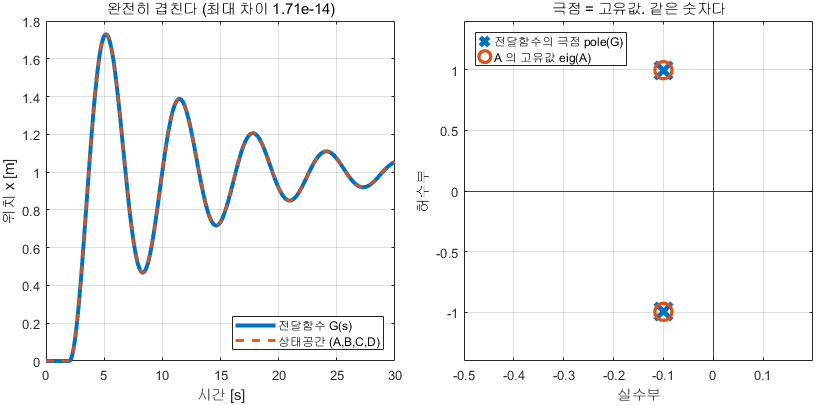

응답도 겹치고 극점도 같다 — 표기만 다를 뿐 같은 시스템

**그림 파일** `w03_ss_vs_tf.png` — `make_figures.m` 의 `fig_w03_ss_vs_tf` · 다시 만들려면 `make_figures('w03_ss_vs_tf')`

**만드는 곳** — `make_figures.m` 의 `fig_w03_ss_vs_tf` **직접 확인해 보려면** — `W03_02_state_space.m` 의 **4절** (`tf2ss`, `ss2tf` 왕복)

그림 해석

그래서 `ss` 든 `tf` 든 편한 쪽을 쓰면 됩니다. 손해 보는 것이 없습니다.

## 6. 상태공간이 좋은 이유

2주차 마지막에 풀지 못한 문제가 있었습니다.

**"물체를 **$0.5\,\mathrm{m}$** 당겨 놓고 힘 없이 놓았다. 어떻게 되는가?"**

- 전달함수 — 입력이 $0$ 이니 출력도 $0$. **틀린 답**

- 상태공간 — 초기 상태를 직접 넣을 수 있으니 **제대로 답함**

게다가 **내부 상태를 전부 볼 수 있습니다.** 위치뿐 아니라 속도까지요.

아래 그림에서 위치가 최대일 때 속도가 $0$ 이고, 위치가 $0$ 을 지날 때 속도가 최대인 것을 확인하십시오. 그네를 떠올리면 자연스러운 결과입니다.

sys_all = ss(p.A, p.B, eye(2), [0;0]);
t2 = 0:0.01:40;
y_all = initial(sys_all, [0.5;0], t2);
tiledlayout(2,1)
nexttile
plot(t2, y_all(:,1), 'LineWidth',2); grid on
ylabel('위치 [m]'); title('내부 상태를 모두 꺼내 본 결과')
nexttile
plot(t2, y_all(:,2), 'LineWidth',2, 'Color',[0.85 0.33 0.10]); grid on
xlabel('시간 [s]'); ylabel('속도 [m/s]')

이점을 네 가지로 정리하면 이렇습니다. 넷째 칸이 **이 과목 후반부 전체**입니다.

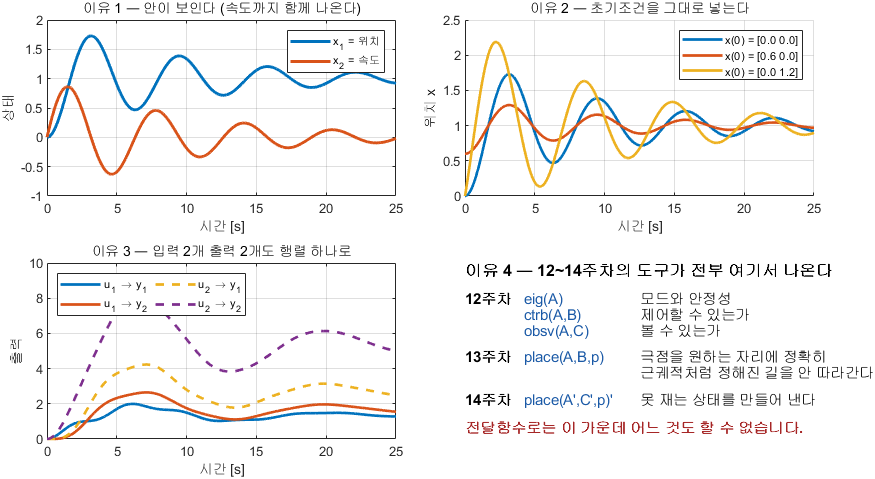

상태공간을 쓰는 이유 네 가지

**그림 파일** `w03_why_ss.png` — `make_figures.m` 의 `fig_w03_why_ss` · 다시 만들려면 `make_figures('w03_why_ss')`

**만드는 곳** — `make_figures.m` 의 `fig_w03_why_ss` **직접 확인해 보려면** — 이유 1·2 는 `W03_02_state_space.m` 의 **6·7절**, 이유 3·4 는 12~14주차 폴더에서 다시 만납니다

그림 해석

## 7. 이제 오늘의 본론 — 선형화

지금까지 배운 도구들(전달함수, 극점, 블록선도, 상태공간)은 전부 **선형 시스템**에서만 통합니다.

선형이란 무엇인가? 정의는 간단합니다.


$$\text{입력을 2배 넣으면 출력도 정확히 2배가 나온다}$$


그런데 현실은 이렇지 않습니다.

- 자동차 액셀을 2배 밟는다고 속도가 2배가 되지 않는다

- 진자를 2배 기울인다고 되돌아오는 힘이 2배가 되지 않는다

현실은 거의 다 비선형입니다. 그렇다면 지금까지 배운 것이 모두 무용한가?

## 8. 아이디어 — 좁게 보면 곡선도 직선이다

지구는 둥급니다. 그런데 동네 지도는 평평하게 그립니다. 왜 문제가 되지 않는가? **좁은 영역이기 때문입니다.**

- 세계지도를 평평하게 그리면 그린란드가 아프리카만 해진다 → 크게 틀림

- 우리 동네 정도면 평평하다고 해도 거의 안 틀림

선형화가 정확히 이겁니다. 곡선 전체를 직선으로 바꾸는 게 아니라 **관심 있는 한 점 근처만** 직선으로 바꿉니다. 그 점을 **동작점** 또는 **평형점**이라고 부릅니다.

x = -2:0.01:2;
plot(x, sin(x), 'LineWidth',3); hold on
plot(x, x, '--', 'LineWidth',2)
plot(0,0,'ko','MarkerSize',10,'MarkerFaceColor','k')
grid on; ylim([-1.5 1.5]); xlabel('x [rad]'); ylabel('값')
title('sin(x) 와 직선 x : 원점 근처에서는 거의 같다')
legend('sin(x)  진짜 곡선','x  직선 근사','Location','southeast')

## 9. 얼마나 좁아야 "좁은" 건가

말로만 하면 감이 안 오니 숫자로 봅니다. $\sin\theta$ 를 $\theta$ 로 바꿨을 때 몇 퍼센트나 틀리는지 계산합니다.

표를 읽어 보면 대략 이렇습니다.

- $10^\circ$ 까지는 오차 $0.5\%$ — 아무 문제 없음

- $30^\circ$ 가 되면 $5\%$ — 슬슬 신경 쓰임

- $60^\circ$ 면 $21\%$ — 이제 못 씀

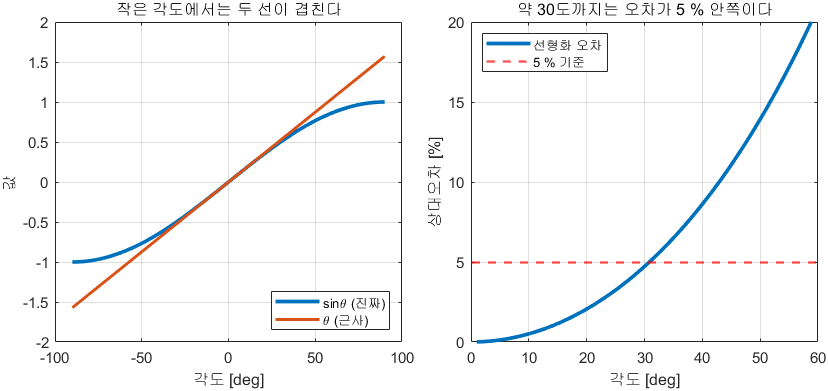

약 30도까지는 선형화 오차가 5 % 안쪽이다

**그림 파일** `w03_linearize.png` — `make_figures.m` 의 `fig_linearize` · 다시 만들려면 `make_figures('w03_linearize')`

**만드는 곳** — `make_figures.m` 의 `fig_linearize` **직접 바꿔 보려면** — `W03_03_pendulum_linearization.m` 의 **2·3절**

그림 해석

그런데 실무에서는 "$30^\circ$ 까지 된다" 보다 **"몇 도까지가 **$1\%$** 인가"** 를 씁니다. 그 경계를 숫자로 못 박아 둡시다.

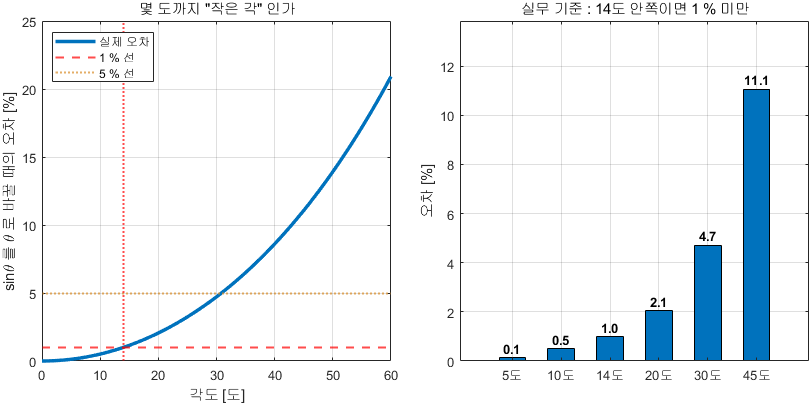

1 % 를 기준으로 하면 경계는 14도다

**그림 파일** `w03_how_narrow.png` — `make_figures.m` 의 `fig_w03_how_narrow` · 다시 만들려면 `make_figures('w03_how_narrow')`

**만드는 곳** — `make_figures.m` 의 `fig_w03_how_narrow` **직접 바꿔 보려면** — 명령창에서 `fzero` 의 기준값 `0.01` 을 `0.05` 로 바꾸면 $5\%$ 기준의 경계가 나옵니다 (약 $31^\circ$)

그림 해석

외울 숫자는 하나입니다 — $14^\circ$. 이 안쪽이면 마음 놓고 선형 모델을 씁니다.

for dg = [1 5 10 20 30 45 60 90]
    th = deg2rad(dg);
    fprintf('%4d도 : sin=%.4f, theta=%.4f, 오차 %.1f %%\n', ...
            dg, sin(th), th, abs(th-sin(th))/sin(th)*100);
end

## 9-1. 선형화의 근거 — 테일러 급수

앞 절까지는 "$\sin\theta$ 를 $\theta$ 로 바꾼다" 를 **그림으로만** 정당화했습니다. 이제 근거를 식으로 적습니다. 근거는 테일러 급수 하나뿐입니다.

어떤 함수 $f$ 를 점 $x_0$ 근처에서 다음과 같이 전개할 수 있습니다.


$$f(x_0 + \Delta x) = f(x_0) + f'(x_0)\,\Delta x + \frac{1}{2}f''(x_0)\,\Delta x^2 + \frac{1}{6}f'''(x_0)\,\Delta x^3 + \cdots$$


여기서 **1차 항까지만 남기고 나머지를 버리는 것**이 선형화입니다.


$$f(x_0 + \Delta x) \;\approx\; f(x_0) + f'(x_0)\,\Delta x$$


오른쪽 식을 보십시오. $\Delta x$ 에 대해 **상수 더하기 상수 곱하기**입니다. 즉 직선입니다. 이것이 선형화의 전부입니다.

$\sin\theta$ 를 $\theta_0 = 0$ 에서 전개하면 다음과 같습니다.


$$\sin\theta = \theta - \frac{\theta^3}{6} + \frac{\theta^5}{120} - \cdots$$


1차 항만 남기면 $\sin\theta \approx \theta$ 가 됩니다. 9절에서 그림으로 확인한 그 근사가 여기서 나온 것입니다.

**버린 항이 곧 오차입니다.** 그러므로 오차의 크기는 미리 알 수 있습니다.


$$\left|\sin\theta - \theta\right| \;\approx\; \frac{|\theta|^3}{6}$$


$\Delta x$ 가 절반이 되면 오차는 $1/8$ 로 줄어듭니다. "좁게 보면 된다" 는 말의 정량적 의미가 이것입니다.

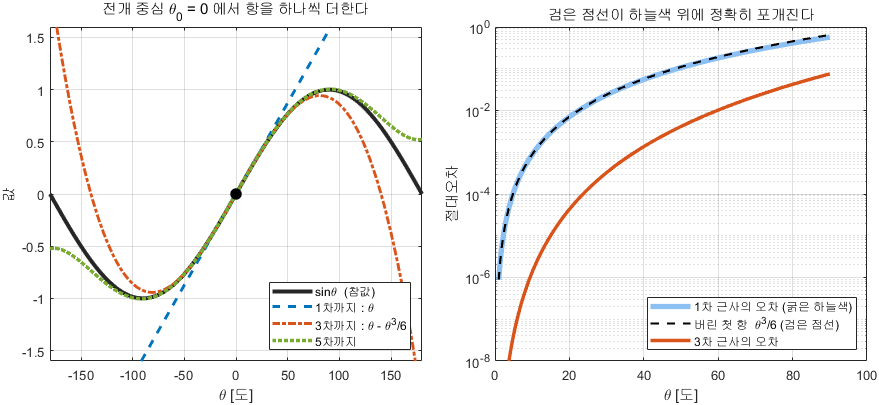

항을 하나씩 더하면 근사가 어디까지 따라오는가

**그림 파일** `w03_taylor.png` — `make_figures.m` 의 `fig_w03_taylor` · 다시 만들려면 `make_figures('w03_taylor')`

**만드는 곳** — `make_figures.m` 의 `fig_w03_taylor` **직접 확인해 보려면** — 명령창에서 `taylor(sin(x), x, 'Order', 6)` 을 실행하면 위 급수를 MATLAB 이 직접 보여 줍니다

그림 해석

여기서 중요한 결론이 하나 나옵니다. **항을 더 남기면 근사는 좋아지지만, 그 순간 식이 다시 비선형이 됩니다.** $\theta^3$ 항이 있으면 중첩원리가 성립하지 않습니다. 그러므로 이 과목에서는 **반드시 1차 항까지만** 남깁니다.

## 9-2. 변수가 여럿일 때 — 편미분과 야코비안

진자의 상태는 두 개이고 입력도 있습니다. 변수가 여럿일 때는 미분 대신 **편미분**을 쓰고, 그 결과를 행렬로 모읍니다.

비선형 상태방정식을 다음과 같이 적습니다.


$$\dot{x} = f(x, u)$$


여기서 $x$ 는 $n$ 차원 상태벡터, $u$ 는 입력입니다. $f$ 는 각 성분이 $f_1, f_2, \ldots, f_n$ 인 벡터함수입니다.

동작점 $(x_0, u_0)$ 근처에서 각 성분을 테일러 전개하고 1차 항만 남기면


$$\dot{x}_i \;\approx\; f_i(x_0, u_0) + \sum_{j=1}^{n}\left.\frac{\partial f_i}{\partial x_j}\right|_{0}\Delta x_j + \left.\frac{\partial f_i}{\partial u}\right|_{0}\Delta u$$


이것을 행렬로 묶으면 우리가 아는 두 줄이 됩니다.


$$\Delta\dot{x} = A\,\Delta x + B\,\Delta u$$



$$a_{ij} = \left.\frac{\partial f_i}{\partial x_j}\right|_{(x_0,u_0)}, \qquad b_{i} = \left.\frac{\partial f_i}{\partial u}\right|_{(x_0,u_0)}$$


이 두 행렬을 **야코비안**이라 부릅니다. 강의자료 `03_Modeling` 의 slide 40 $\sim$ 42 가 같은 유도입니다.

기하학적으로는 이렇습니다. 1변수에서 곡선을 접선으로 바꾸었다면, 2변수에서는 **곡면을 접평면으로** 바꿉니다.

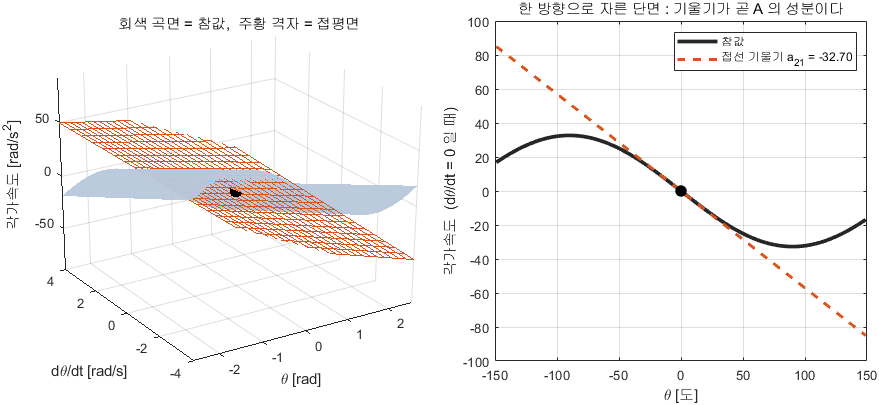

곡면을 한 점에서 접평면으로 바꾸는 것이 야코비안이다

**그림 파일** `w03_jacobian.png` — `make_figures.m` 의 `fig_w03_jacobian` · 다시 만들려면 `make_figures('w03_jacobian')`

**만드는 곳** — `make_figures.m` 의 `fig_w03_jacobian` **직접 확인해 보려면** — `W03_05_linearize_verify.m` 의 **2 **$\sim$** 4절**

그림 해석

진자에 이 정의를 적용하면 다음과 같습니다.


$$f(x,u) = \left[\begin{array}{c} x_2 \\[2pt] \frac{u - b x_2 - mgl\sin x_1}{J} \end{array}\right]$$



$$A = \left[\begin{array}{cc} 0 & 1 \\[2pt] -\frac{mgl\cos\theta_0}{J} & -\frac{b}{J} \end{array}\right], \qquad B = \left[\begin{array}{c} 0 \\[2pt] \frac{1}{J} \end{array}\right]$$


$A$ 의 $(2,1)$ 성분에 $\cos\theta_0$ 가 들어 있습니다. **동작점이 바뀌면 이 성분이 바뀌고, 부호까지 뒤집힐 수 있습니다.** 12절에서 이 한 성분이 시스템의 성격을 정반대로 만드는 것을 봅니다.

## 9-3. 동작점을 먼저 정한다 — 평형점 조건

선형화 식에는 $(x_0, u_0)$ 가 들어 있습니다. **그 점을 먼저 정하지 않으면 선형화 자체를 시작할 수 없습니다.**

아무 점이나 쓸 수는 있지만, 그러면 $f(x_0,u_0) \ne 0$ 이므로 상수항이 남아 다음과 같이 됩니다.


$$\Delta\dot{x} = A\,\Delta x + B\,\Delta u + f(x_0,u_0)$$


맨 오른쪽 $f(x_0,u_0)$ 가 상수항입니다.

상수항이 있으면 $\Delta x = 0$ 이어도 상태가 계속 움직이므로 표준형 $\dot{x} = Ax + Bu$ 가 되지 않습니다. 그래서 **평형점을 고릅니다.** 평형점의 정의는 한 줄입니다.


$$f(x_0, u_0) = 0$$


진자에서 이 식을 풀면 두 조건이 나옵니다.


$$\dot\theta_0 = 0, \qquad u_0 = mgl\sin\theta_0$$


첫 줄은 "정지해 있어야 한다", 둘째 줄은 "중력 토크를 정확히 상쇄하는 토크를 계속 넣고 있어야 한다" 는 뜻입니다. $u_0 = 0$ 으로 두면 $\sin\theta_0 = 0$ 이므로 $\theta_0 = 0$ 또는 $\theta_0 = \pi$ 입니다. **평형점이 두 개**이고, 이것이 12절의 출발점입니다.

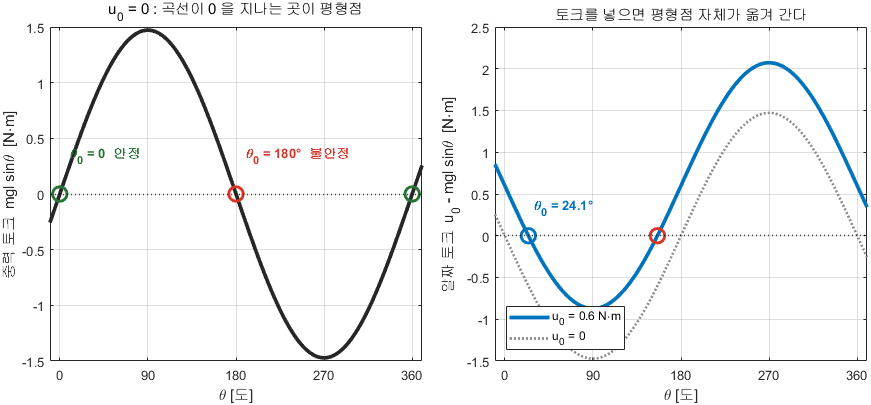

평형점은 알짜 토크가 0 이 되는 자리다

**그림 파일** `w03_equilibrium.png` — `make_figures.m` 의 `fig_w03_equilibrium` · 다시 만들려면 `make_figures('w03_equilibrium')`

**만드는 곳** — `make_figures.m` 의 `fig_w03_equilibrium` **직접 확인해 보려면** — `W03_05_linearize_verify.m` 의 **1절**이 `fzero` 로 두 평형점을 실제로 찾아 출력합니다

그림 해석

마지막 줄이 중요합니다. $u_0 > mgl$ 이면 평형점이 **하나도 없습니다.** 아무리 큰 토크를 넣어도 진자가 멈추지 못하고 계속 도는 상태입니다. 이런 경우에는 선형화할 자리 자체가 없습니다.

## 9-4. 편차 변수 — 선형 모델의 원점은 평형점이다

선형 모델의 변수는 $x$ 가 아니라 $\Delta x = x - x_0$ 입니다. **이 구분을 놓치면 뒤에서 반드시 사고가 납니다.**

정리하면 이렇습니다.

그러므로 실제 시스템에 넣는 입력은 다음과 같습니다.


$$u = u_0 + \Delta u = u_0 - K\,(x - x_0)$$


$u_0$** 를 빠뜨리면** 평형을 유지하는 힘이 없어 제어기가 아무리 잘 설계되어도 시스템이 동작점에서 벗어납니다. $x_0$** 를 빼지 않으면** 제어기가 절대 각도를 오차로 착각해 반대로 밉니다.

13주차에서 거꾸로 선 진자를 세울 때 이 두 항이 그대로 다시 나옵니다. 그때 좌표를 혼동하면 결과가 전혀 다르게 나오므로 지금 확실히 해 두십시오.

## 10. 진자에서 확인하기

줄 끝에 추가 달린 진자입니다. $\theta$ 는 아래쪽 수직에서 잰 각도이므로 가만히 매달려 있으면 $\theta = 0$ 입니다.

운동방정식은 이렇습니다.


$$ml^2\ddot{\theta} = u - b\dot{\theta} - mgl\sin\theta$$


이 식이 어디서 나오는지는 자유물체도 한 장이면 끝납니다.

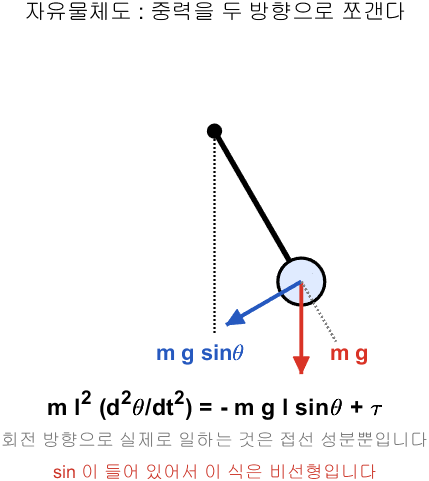

중력을 두 방향으로 쪼개면 sin 이 나온다

**그림 파일** `pendulum_fbd.png` — `common/dg_pendulum.m` 의 `dg_pendulum` · 다시 만들려면 `make_figures('pendulum_fbd')`

**만드는 곳** — `common/dg_pendulum.m` 을 `dg_pendulum('fbd')` 로 부릅니다 (`make_figures('pendulum_fbd')`) **직접 확인해 보려면** — `W03_03_pendulum_linearization.m` 의 **4절**

그림 해석

여기서 중력 토크가 $mgl\sin\theta$ 입니다. **이 **$\sin$** 하나 때문에 비선형이 됩니다.** $\theta$ 가 작다고 보고 $\sin\theta \approx \theta$ 로 바꾸면 선형이 됩니다.


$$ml^2\ddot{\theta} = u - b\dot{\theta} - mgl\,\theta$$


상태공간으로 적으면 $A$ 행렬은 이렇게 됩니다.


$$A = \left[\begin{array}{cc} 0 & 1 \\ -\frac{mgl\cos\theta_0}{J} & -\frac{b}{J} \end{array}\right]$$


$\cos\theta_0$ 가 들어가는 것은 **어느 점에서 폈느냐에 따라 기울기가 다르기** 때문입니다.

먼저 $5^\circ$ 에서 놓아 봅니다. 두 선이 겹쳐서 하나로 보입니다.

[sysLin, pp] = plant_pendulum(0);
t3 = linspace(0,10,1000)';
[tn, xn] = ode45(@(t,x) pp.f(x,0), [0 10], [deg2rad(5); 0]);
plot(tn, rad2deg(xn(:,1)), 'LineWidth',3); hold on
plot(t3, rad2deg(initial(sysLin,[deg2rad(5);0],t3)), '--', 'LineWidth',2)
yline(0,'k:'); grid on; xlabel('시간 [s]'); ylabel('각도 [도]')
title('5도에서 놓았을 때 : 두 선이 거의 겹친다')
legend('비선형 (진짜)','선형 근사','Location','northeast')

## 11. 크게 흔들면 갈라집니다

이번엔 $60^\circ$ 에서 놓아 봅니다. 9절 표에서 $60^\circ$ 면 $21\%$ 틀린다고 했습니다.

결과를 보면 시간이 갈수록 두 선의 박자가 어긋나다가 결국 전혀 다른 결과를 냅니다.

**왜 그러한가?**

- 진짜 진자는 크게 흔들수록 한 번 왕복하는 시간이 길어진다

- 크게 벌어진 지점에서는 중력이 되돌리는 힘이 생각만큼 크지 않기 때문 ($\sin 60^\circ = 0.87$ 로, $60^\circ = 1.05\,\mathrm{rad}$ 보다 한참 작다)

- 선형 모델은 이걸 모르고 각도와 상관없이 항상 같은 주기라고 본다

[tn2, xn2] = ode45(@(t,x) pp.f(x,0), [0 10], [deg2rad(60); 0]);
plot(tn2, rad2deg(xn2(:,1)), 'LineWidth',3); hold on
plot(t3, rad2deg(initial(sysLin,[deg2rad(60);0],t3)), '--', 'LineWidth',2)
yline(0,'k:'); grid on; xlabel('시간 [s]'); ylabel('각도 [도]')
title('60도에서 놓았을 때 : 시간이 갈수록 어긋난다')
legend('비선형 (진짜)','선형 근사','Location','northeast')

## 12. 오늘의 하이라이트 — 같은 진자, 다른 자리

진자를 거꾸로 세워 봅니다. $\theta = 180^\circ$ 입니다. 손을 떼지 않으면 그 자세로 가만히 있으니 **여기도 평형점**입니다.

물리적으로는 **완전히 같은 진자**이고 방정식도 그대로입니다. 그런데 이 자리에서 선형화하면 **전혀 다른 모델**이 나옵니다.

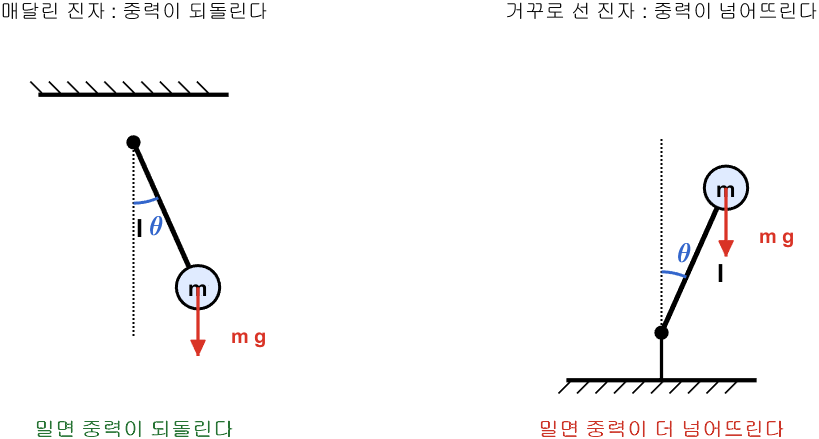

같은 진자를 두 자세로 놓고 밀어 보면 중력이 하는 일이 정반대다

**그림 파일** `pendulum_compare.png` — `common/dg_pendulum.m` 의 `dg_pendulum` · 다시 만들려면 `make_figures('pendulum_compare')`

**만드는 곳** — `common/dg_pendulum.m` 을 `dg_pendulum('compare')` 로 부릅니다 (`make_figures('pendulum_compare')`) **직접 확인해 보려면** — `W03_03_pendulum_linearization.m` 의 **7절**

그림 해석

두 그림에서 **바뀐 것은 축이 위에 있느냐 아래에 있느냐뿐**입니다. 그 하나가 $A$ 행렬 안 $\cos\theta_0$ 의 부호를 뒤집고, 고유값의 부호를 뒤집습니다.

이유는 $A$ 행렬 안의 $\cos\theta_0$ 입니다.

- $\theta_0 = 0$ 이면 $\cos\theta_0 = +1$ → 중력이 되돌린다 → **안정**

- $\theta_0 = 180^\circ$ 면 $\cos\theta_0 = -1$ → 중력이 넘어뜨린다 → **불안정**

**부호 하나가 뒤집히면서 시스템의 성격이 정반대가 됩니다.**

거꾸로 선 쪽은 고유값 하나가 양수가 되고, 2주차에서 배웠듯이 양수 고유값은 발산을 뜻합니다. 조금만 기울어도 그대로 넘어간다는 것입니다.

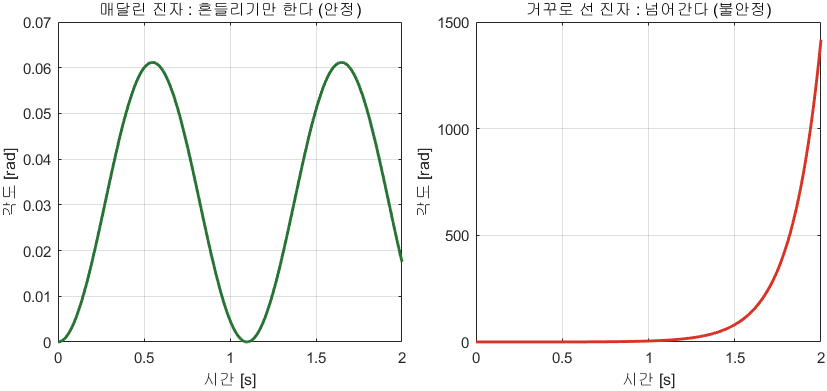

같은 진자인데 자세가 다르면 결과가 정반대다

**그림 파일** `w03_pendulum_resp.png` — `make_figures.m` 의 `fig_pend_resp` · 다시 만들려면 `make_figures('w03_pendulum_resp')`

**만드는 곳** — `make_figures.m` 의 `fig_pend_resp` **직접 확인해 보려면** — `W03_03_pendulum_linearization.m` 의 **7절**을 실행하면 두 자세의 고유값이 나란히 출력됩니다

그림 해석

오른쪽 값 $1400\,\mathrm{rad}$ 은 물리적으로는 말이 안 되는 숫자입니다 (진자가 $200$ 바퀴 넘게 돌았다는 뜻이기 때문입니다). **선형 모델이 자기 유효범위를 벗어나서도 계속 계산한 결과**입니다. 이것이 14절에서 말할 "반드시 비선형 모델로 되돌아가 검증하라" 의 이유입니다.

[~, pUp] = plant_pendulum(pi);
fprintf('매달린 자세 고유값 : %s\n', mat2str(round(eig(pp.A),2)));
fprintf('거꾸로 자세 고유값 : %s\n', mat2str(round(eig(pUp.A),2)));

## 13. Simulink 로 보면 더 확실합니다

모델 `W03_Pendulum_NonlinVsLin.slx` 를 열어 보십시오.

위아래 두 경로가 **블록 구성이 완전히 똑같습니다.** 딱 하나, 위쪽에만 `sin` 블록이 들어 있습니다.

즉 **선형화란 이 sin 블록을 떼어내는 일입니다.** 그게 전부입니다. 이보다 더 명확한 그림은 없습니다.

모델은 모델을 열고 `Ctrl+T` 를 눌러도 실행됩니다. `W03_04_run_simulink.m` 을 실행하면 여러 각도에서 차이를 표로 뽑아 줍니다.

- $5^\circ$ — 차이 $0.1^\circ$ · 거의 같음

- $20^\circ$ — 차이 $8^\circ$ · 조금 다름

- $60^\circ$ — 차이 $120^\circ$ · 많이 다름

- $100^\circ$ — 차이 $200^\circ$ · 전혀 다른 결과

여기서 한 가지를 짚어 두어야 합니다. 이 모델의 아래쪽 경로는 $\theta_0 = 0$** 에서 손으로 선형화한 결과를 사람이 블록으로 옮겨 그린 것**입니다. 블록이 열 개 남짓이라 가능했습니다. 블록이 수백 개인 실무 모델에서는 이 작업을 사람이 할 수 없습니다. 그래서 도구를 씁니다.

## 13-1. `linearize` — Simulink 모델을 그대로 선형화한다

Simulink Control Design 의 `linearize` 는 블록선도를 **있는 그대로** 받아 지정한 동작점에서 수치 선형화하여 `ss` 객체를 돌려줍니다.

먼저 입출력을 지정해야 합니다.

`linio` 명령 정리

- **원리** — 모델의 어느 신호를 입력으로, 어느 신호를 출력으로 볼지 표시한다

- **입력** — `linio('블록경로', 포트번호, 종류)`. 종류는 `'input'` 또는 `'output'`

- **출력** — 선형화 입출력점 객체. 여러 개를 배열로 모아 `linearize` 에 넘긴다

- **주의 1** — 신호 이름이 아니라 **블록 경로와 출력 포트 번호**를 준다

- **주의 2** — 입력점은 그 신호를 **끊는 것이 아니라** 주입 지점을 표시하는 것이다

`linearize` 명령 정리

- **원리** — 각 블록의 국소 야코비안을 구해 전체를 이어 붙인다

- **입력** — `linearize(모델이름, io)` 또는 `linearize(모델이름, io, op)`

- **출력** — 상태공간 모델 (`ss` 객체)

- **주의 1** — `op` 를 주지 않으면 **모델의 초기조건**을 동작점으로 쓴다. 그러므로 적분기 초기값을 평형점에 맞춰 두어야 의미 있는 결과가 나온다

- **주의 2** — 동작점이 평형점이 아니면 결과는 나오지만 **틀린 모델**이다. 9-3절의 상수항이 무시되기 때문이다

실제로 쓰면 세 줄입니다.

- `io(1) = linio([model '/입력 토크'], 1, 'input');`

- `io(2) = linio([model '/적분 각속도에서 각도 비선형'], 1, 'output');`

- `sysSL = linearize(model, io);`

`W03_05_linearize_verify.m` 의 **6절**이 이 세 줄을 그대로 실행합니다.

## 13-2. 네 가지 방법의 답이 같은지 대조한다

야코비안을 구하는 방법은 네 가지가 있고, **답은 반드시 같아야 합니다.** 다르면 어느 하나가 틀린 것이므로, 이 대조 자체가 검증 절차입니다.

`W03_05_linearize_verify.m` 을 실행하면 네 결과가 나란히 출력됩니다. 이 진자에서는 다음과 같이 나옵니다.

수치 미분과 `linearize` 의 차이가 정확히 $0$ 이 아닌 것은 유한한 스텝으로 미분을 근사하기 때문입니다. $10^{-11}$ 수준이면 같다고 봅니다.

한 가지 더 확인합니다. 같은 모델에서 적분기 초기값만 $\pi$ 로 바꾸면 `linearize` 의 결과가 다음과 같이 달라집니다.

**블록은 하나도 바꾸지 않았습니다.** 바꾼 것은 동작점 하나뿐입니다. 12절에서 손으로 얻은 결론을 도구가 그대로 재현한 것입니다.

## 13-3. 선형 모델을 정량적으로 검증한다

선형 모델을 만든 것으로 끝이 아닙니다. **몇 도까지 믿어도 되는지를 숫자로 정해야** 설계에 쓸 수 있습니다.

검증 절차는 세 단계입니다.

- 같은 초기조건을 비선형 모델과 선형 모델에 각각 준다

- 두 응답의 최대 차이를 비선형 응답의 크기로 나눈다 (상대오차)

- 초기각을 키워 가며 이 오차가 기준을 넘는 지점을 찾는다

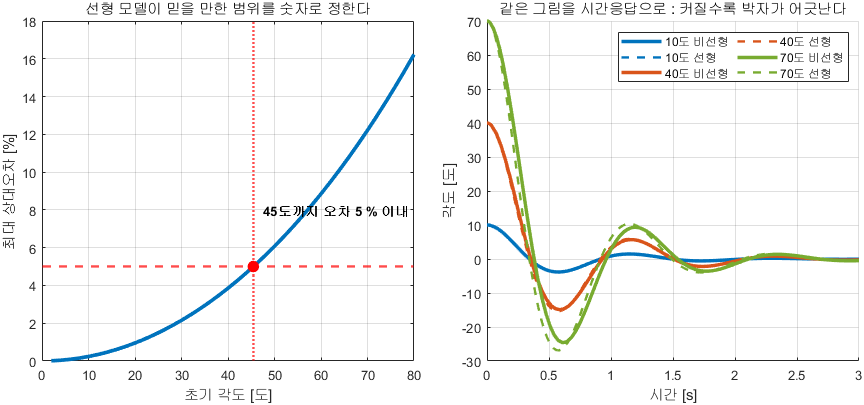

응답 오차로 유효 범위를 정한다

**그림 파일** `w03_valid_range.png` — `make_figures.m` 의 `fig_w03_valid_range` · 다시 만들려면 `make_figures('w03_valid_range')`

**만드는 곳** — `make_figures.m` 의 `fig_w03_valid_range` **직접 확인해 보려면** — `W03_05_linearize_verify.m` 의 **7절**

그림 해석

여기서 주의할 것이 하나 있습니다. 9절에서 $\sin\theta$ 를 $\theta$ 로 바꿀 때의 오차가 $5\%$ 가 되는 각도는 $31^\circ$ 였는데, 응답으로 잰 유효 범위는 $45^\circ$ 입니다.

정적 기준이 더 보수적입니다. 진자는 한 주기 동안 각도가 커졌다 작아졌다 하므로 최대 각도에서만 오차가 크고 대부분의 시간에는 작기 때문입니다. **설계 초기에는 정적 기준으로 대략 잡고, 최종 확인은 응답으로 하십시오.**

## 14. 이것이 실무에서 뜻하는 것

선형 모델로 제어기를 설계했다면, 그 제어기는 **각도가 작게 유지되는 동안만** 제대로 동작합니다.

그래서 실무 순서는 항상 이렇습니다.

- 비선형 모델을 만든다

- 동작점 근처에서 선형화한다

- 선형 모델로 제어기를 설계한다 (여기서 우리가 배운 도구를 쓴다)

- **설계한 제어기를 다시 비선형 모델에 붙여서 검증한다**

마지막 단계를 빼먹으면 시뮬레이션에서는 멀쩡한데 실제로는 터지는 일이 생깁니다. 반드시 습관으로 만드십시오.

## 14-1. 왜 이 과목은 선형 모델을 기준으로 두는가

이 절이 3주차 전체의 결론입니다.

이 과목이 다루는 도구를 나열해 보면 이렇습니다.

**오른쪽 칸이 전부 "선형" 입니다.** 예외가 하나도 없습니다.

그 이유는 두 가지입니다.

- **중첩원리** — 입력을 나누어 넣고 답을 더할 수 있어야 전달함수가 정의된다. 비선형에서는 $G(s)$ 라는 개념 자체가 성립하지 않는다

- **정현입력에 정현출력** — 주파수응답 전체가 이 성질 위에 서 있다. 비선형 시스템에 사인을 넣으면 없던 주파수 성분이 생겨 나온다

그러므로 이 과목에서 **기준 모델은 언제나 선형 모델**입니다. 비선형 모델은 두 곳에서만 등장합니다.

- 선형 모델을 **만들어 내는 출발점**으로 (오늘 9 $\sim$ 13절)

- 설계가 끝난 뒤 **최종 검증 대상**으로 (13주차, 14주차)

이 두 자리를 정확히 구분하는 것이 3주차의 목표입니다.

정리하면 설계의 전체 흐름은 다음과 같습니다.

5단계가 학기의 대부분을 차지하지만, 그것이 성립하려면 **2 **$\sim$** 4단계가 먼저 제대로 되어 있어야 합니다.**

## 15. 오늘의 정리

- 블록선도는 직렬은 곱하고, 병렬은 더하고, 되먹임은 $\frac{G}{1+GH}$

- 상태는 미래를 계산하는 데 필요한 최소한의 정보. 게임 세이브 파일과 같다

- 상태공간은 항상 $\dot{x}=Ax+Bu$, $y=Cx+Du$ 두 줄. $A$ 의 고유값이 극점이다

- 세상은 비선형이지만 한 점 근처에서는 직선으로 봐도 된다. 이것이 선형화다

- 선형화의 근거는 **테일러 급수의 1차 항까지만 남기는 것**이고, 버린 첫 항의 크기가 곧 오차의 크기다

- 변수가 여럿이면 편미분을 모아 **야코비안** $A$, $B$ 를 만든다

- 선형화는 **동작점을 정하는 것에서 시작**한다. 평형점은 $f(x_0,u_0)=0$ 의 해다

- 선형 모델이 다루는 값은 절대값이 아니라 **편차** $\Delta x = x - x_0$ 다

- 진자에서는 $\sin\theta \to \theta$ 가 선형화이고, Simulink 로 보면 `sin` 블록을 떼어내는 것과 정확히 같다

- 같은 시스템이라도 **어느 점에서 폈느냐**에 따라 안정한 모델이 나오기도 하고 불안정한 모델이 나오기도 한다

- 야코비안은 손 · 기호(`jacobian`) · 수치 · 모델(`linearize`) 네 가지로 구할 수 있고, **네 답이 같은지 대조하는 것 자체가 검증**이다

- 선형 모델은 만든 것으로 끝이 아니라 **유효 범위를 숫자로 정해야** 한다. 이 진자는 응답 기준으로 약 $45^\circ$ 다

- 이 과목의 설계 도구는 전부 LTI 를 전제하므로 **선형 모델이 기준 모델**이고, 비선형 모델은 출발점과 최종 검증 대상으로만 쓴다

## 다음 주 예고

4주차에서는 **시간응답**을 다룹니다.

지금까지 "빠르다", "진동한다" 같은 말을 감으로 써 왔는데, 이제 이것을 숫자로 적는 법을 배웁니다. 오버슈트가 몇 퍼센트인지, 정착시간이 몇 초인지 같은 것입니다.

그리고 이 숫자들이 극점 위치와 어떻게 연결되는지 알게 됩니다. **"오버슈트를 **$10\%$** 이하로 하려면 극점을 어디에 두어야 하는가"** 같은 질문에 답할 수 있게 되는데, 이것이 6주차 제어기 설계의 출발점이 됩니다.